# 1CWK50 - Zivile Aponaviciute - 19091621

## 1.a Filesize-based features - Issue A

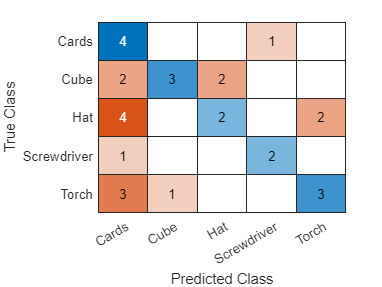

% check the dataset is present:
if ~exist('MerchData.csv', 'file')
    error('You need to download MerchData.csv from Moodle and place it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% Load table

merchData = readtable('MerchData.csv');

% Randomise and split table

%get the size needed for training set (60%)
trainingSize = (size(merchData, 1) * 60) / 100;
%get the size needed for testing set (40%)
testingSize = (size(merchData, 1) * 40) / 100;
%randomise the rows of the table; so that both training and testing arrays contain fair amount of different examples
randData = merchData(randperm(size(merchData,1)), :); 

%get the first 60% rows from the randomized row to place in training set
trainingData = head (randData, trainingSize);
%get the last 40% rows from the randomized row
testingData = tail (randData, testingSize); 

% Separate class labels and examples

%seperating labels from sets to be able to compare predictions
trainingLabels = categorical(table2array(trainingData(:, end:end))); 
%converting table to array and to a categorical array; using categorical
%array as it is the most efficient type of array for the nonnumerical values
testingLabels = categorical(table2array(testingData(:,end:end)));

%removing last column; last column contains labels, that need to be 
%seperate in order for the AI to be able to do predictions
trainingData(:, end:end) = []; 
testingData(:,end:end) = [];

%converting features to a numeric array
trainingData = table2array(trainingData); 
testingData = table2array(testingData);

% Train a k-NN classifier with k = 3

X = trainingData;
Y = trainingLabels;
Mdl = fitcknn(X,Y,'NumNeighbors',3,'Standardize',1);

% Predict labels

predictedLabel = predict(Mdl,testingData);

% Evaluate predictions

cm = confusionchart(testingLabels,predictedLabel);


% Number of correct predictions - 14/30. Accuracy - 46.6%

## 1.b k-NN classifier - Issue B


predic = knn_predict(knn_fit(trainingData, trainingLabels), testingData);

## 2.a Brightness-based features - Issue A

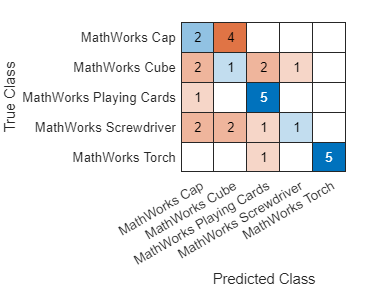

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% Load dataset

%using foldernames for labels
imds = imageDatastore('MerchData', 'IncludeSubfolders', true, 'LabelSource','foldernames'); 

% Randomise and split dataset

%shuffeling the datastore
imdsrand = shuffle(imds);
%splitting into training and testing datastores
[trainingimds, testingimds] = splitEachLabel(imdsrand, 0.6); 

% Extract training data

% placing labels from training to a different variable
trainLabels = trainingimds.Labels;
% getting the size of datastore to use in a for loop
fileAmount = size(trainingimds.Files,1);

%looping through images by reading them one by one and running through
%get_brightness function
for i = 1:fileAmount 
    img = readimage(trainingimds,i);
    trainExamples(i,1) = get_brightness(img);
end

% Train classifier

X = trainExamples;
Y = trainLabels;
Mdl = fitcknn(X,Y,'NumNeighbors',3,'Standardize',1);

% Set up testing data and evaluate classifier

testLabels = testingimds.Labels;
%preparing test examples to use for ai predictions
fileAmount = size(testingimds.Files,1);

for i = 1:fileAmount
    img = readimage(testingimds,i);
    testExamples(i,1) = get_brightness(img);
end

predictedLabel = predict(Mdl,testExamples);

cm = confusionchart(testLabels,predictedLabel);

% Number of correct predictions - 14/30. Accuracy - 46.6%

## 2.b Brightness-based features - Issue B

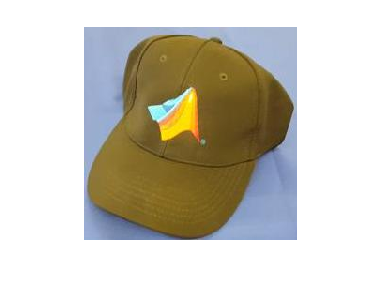

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% Load dataset

%using foldernames for labels
imds = imageDatastore('MerchData', 'IncludeSubfolders', true, 'LabelSource','foldernames'); 

%original image
img = readimage(imds,1);
imshow(img)

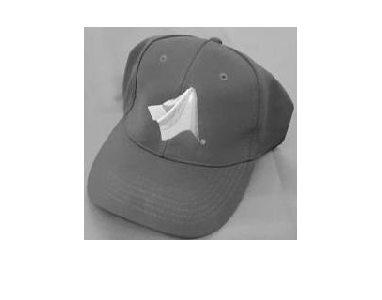


%grayscale image
grayimg = my_im2gray(img);
imshow(grayimg)

## 3.a Edge-based features - Issue A

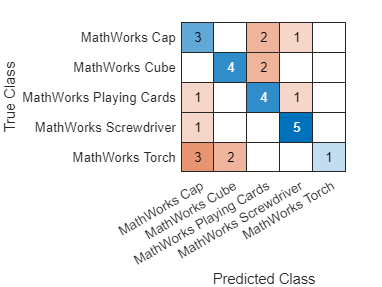

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% Load dataset

%using foldernames for labels
imds = imageDatastore('MerchData', 'IncludeSubfolders', true, 'LabelSource','foldernames'); 

% Randomise and split dataset

%shuffeling the datastore
imdsrand = shuffle(imds);
%splitting into training and testing datastores
[trainingimds, testingimds] = splitEachLabel(imdsrand, 0.6); 

% Extract training data

trainLabels = trainingimds.Labels;
fileAmount = size(trainingimds.Files,1);

%looping through images by reading them one by one and running through
%get_edge function

for i = 1:fileAmount  
        img = readimage(trainingimds,i);
        value = get_edges(img);
        trainExamples(i,1) = value(1,1);
        trainExamples(i,2) = value(1,2);
end

% Train classifier

X = trainExamples;
Y = trainLabels;
Mdl = fitcknn(X,Y,'NumNeighbors',3,'Standardize',1);

% Set up testing data and evaluate classifier

testLabels = testingimds.Labels;

fileAmount = size(testingimds.Files,1);

for i = 1:fileAmount
    img = readimage(testingimds,i);
    value = get_edges(img);
    testExamples(i,1) = value(1,1);
    testExamples(i,2) = value(1,2);
end

predictedLabel = predict(Mdl,testExamples);

cm = confusionchart(testLabels,predictedLabel);


% Number of correct predictions - 17/30. Accuracy - 56.6%

## 4.a HOG-based features - Issue A

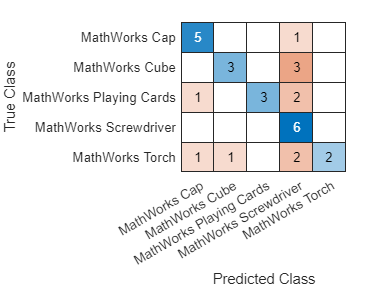

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% Load dataset

%using foldernames for labels
imds = imageDatastore('MerchData', 'IncludeSubfolders', true, 'LabelSource','foldernames'); 

% Randomise and split dataset

%shuffeling the datastore
imdsrand = shuffle(imds);
%splitting into training and testing datastores
[trainingimds, testingimds] = splitEachLabel(imdsrand, 0.6); 

% Extract training data

trainLabels = trainingimds.Labels;
fileAmount = size(trainingimds.Files,1);

%looping through training images by reading them one by one and running through
%get_hogs function
%appending new hog feature array to the training example array
trainExamples = [];
for i = 1:fileAmount  
        img = readimage(trainingimds,i);
        %train_examples(i,1) = get_hogs(img);
        trainExamples=[trainExamples;get_hogs(img)];
end

% Train classifier

X = trainExamples;
Y = trainLabels;
Mdl = fitcknn(X,Y,'NumNeighbors',3,'Standardize',1);

% Set up testing data and evaluate classifier

testLabels = testingimds.Labels;

fileAmount = size(testingimds.Files,1);
testExamples = [];
for i = 1:fileAmount
    img = readimage(testingimds,i);
    testExamples=[testExamples;get_hogs(img)];
end

predictedLabel = predict(Mdl,testExamples);

cm = confusionchart(testLabels,predictedLabel);


% Number of correct predictions - 19/30. Accuracy - 63.3%

## 5.a BoVW-based features - Issue A

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% Load dataset

%using foldernames for labels
imds = imageDatastore('MerchData', 'IncludeSubfolders', true, 'LabelSource','foldernames'); 

% Randomise and split dataset

%shuffeling the datastore
imdsrand = shuffle(imds);
%splitting into training and testing datastores
[trainingimds, testingimds] = splitEachLabel(imdsrand, 0.6); 

% Extracting bag of features

bag = bagOfFeatures(imds);

Creating Bag-Of-Features.
-------------------------
* Image category 1: MathWorks Cap
* Image category 2: MathWorks Cube
* Image category 3: MathWorks Playing Cards
* Image category 4: MathWorks Screwdriver
* Image category 5: MathWorks Torch
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 75 images...done. Extracted 235200 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 188160
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 14/100 iterations (~0.32 seconds/iteration)...converged in 14 iterations.

* Finished creating Bag-Of-Features




% Extract training data

trainLabels = trainingimds.Labels;
fileAmount = size(trainingimds.Files,1);

trainExamples = [];
for i = 1:fileAmount  
        img = readimage(trainingimds,i);
        featureBag = encode(bag,img);
        trainExamples=[trainExamples;featureBag];
end

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features


% Train classifier

X = trainExamples;
Y = trainLabels;
Mdl = fitcknn(X,Y,'NumNeighbors',3,'Standardize',1);

% Set up testing data and evaluate classifier

testLabels = testingimds.Labels;
fileAmount = size(testingimds.Files,1);

testExamples = [];
for i = 1:fileAmount
    img = readimage(testingimds,i);
    featureBag = encode(bag,img);
    testExamples=[testExamples;featureBag];
end

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features

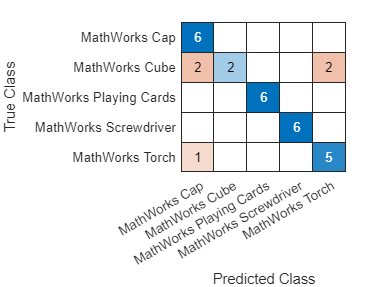


predictedLabel = predict(Mdl,testExamples);

cm = confusionchart(testLabels,predictedLabel);


% Number of correct predictions - 25/30. Accuracy - 83.3%

## 6. CNN-based features - Issue A

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% Load dataset

%using foldernames for labels
imds = imageDatastore('MerchData', 'IncludeSubfolders', true, 'LabelSource','foldernames'); 

% Randomise and split dataset

%shuffeling the datastore
imdsrand = shuffle(imds);
%splitting into training and testing datastores
[trainingimds, testingimds] = splitEachLabel(imdsrand, 0.6); 

% Extract training data

trainLabels = trainingimds.Labels;

net = resnet50();

Error using resnet50 (line 61)
resnet50 requires the Deep Learning Toolbox Model for ResNet-50 Network support package for the pretrained weights. To install this support package, use the Add-On Explorer. To obtain the untrained layers, use resnet50('Weights','none'), which does not require the support package.


imageSize = net.Layers(1).InputSize;
%resizing images, using grayscale
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingimds, 'ColorPreprocessing', 'gray2rgb');
augmentedTestSet = augmentedImageDatastore(imageSize, testingimds, 'ColorPreprocessing', 'gray2rgb');

% Extract train features

featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Train classifier

classifier = fitcecoc(trainingFeatures, trainLabels, ...
    'Learners', 'Linear', 'Coding', 'onevsall', 'ObservationsIn', 'columns');

% Evaluate classifier

%extract test features
testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

predictedLabels = predict(classifier, testFeatures, 'ObservationsIn', 'columns');

testLabels = testingimds.Labels;

cm = confusionchart(testLabels,predictedLabels);

% Number of correct predictions - 29/30. Accuracy - 96.6%